
f1 = 100;
f_carry = 1000;

N_T_og = 5

N_T_og = 5

t_total = N_T_og*(1/f1);  % 1 период огибающей
Fs = 10000;
Ts = 1/Fs;
N = t_total / Ts;  % 200 отсчетов
n = 0:Ts:(N-1)*Ts;
m = 0.5

m = 0.5000

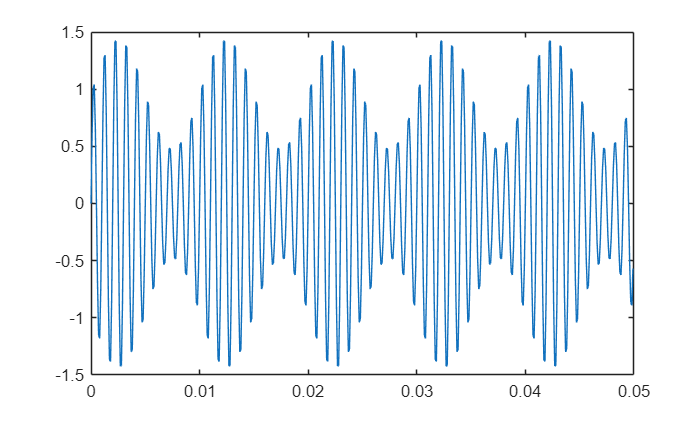


s = (1 + m*sin(2*pi*n*f1)).*sin(2*pi*n*f_carry);
figure
plot(n, s)

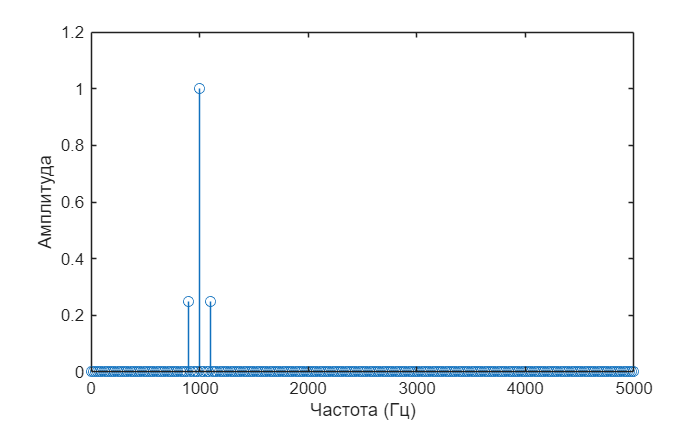

FFT_s = fft(s);
MOD_s = abs(FFT_s);
X_s = 2/N * MOD_s;  % Правильное масштабирование
X_s(1) = X_s(1)/2;  % DC компонент не удваиваем

% Односторонний спектр
X_s_single = X_s(1:N/2+1);
f_axis = (0:N/2) * (Fs/N);

X_s_single = X_s;
f_axis = (0:N-1) * (Fs/N);

stem(f_axis, X_s_single);
xlabel('Частота (Гц)');
ylabel('Амплитуда');
xlim([0 Fs/2]);

f_s = 10000;
%Q = t/T;
T_s = 1/f_s;
N_T_rec = 2;
f = 100;
t_total_rec = N_T_rec*(1/f);
N = (t_total_rec/T_s)*N_T_rec;
n_rec = T_s:T_s:(N)*T_s*N_T_rec;
t = (N)/4;
T = N-t;
s = repmat([ones(1, t) zeros(1, T)], 1, N_T_rec)

s =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


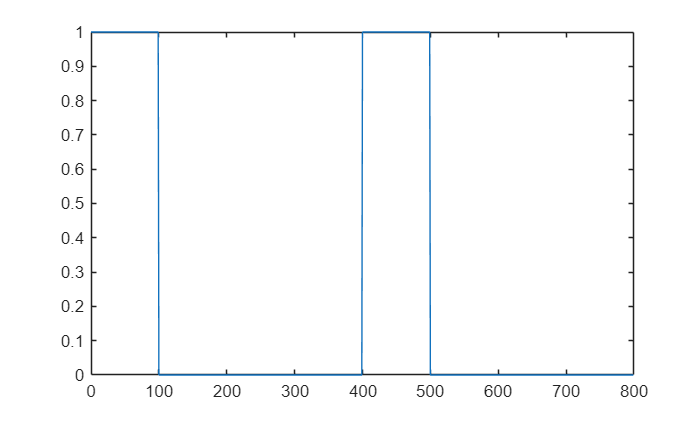


figure;
FFT_s = fft(s);
MOD_s = abs(FFT_s);
X_s = 2/(length(s)/2-1) * MOD_s(1:length(s)/2-1);  % Правильное масштабирование
X_s(1) = X_s(1)/2;  % DC компонент не удваиваем
f_axis = (1:(length(s)/2-1)) * (f_s/(length(s)/2-1));
plot(0:length(s)-1, s)

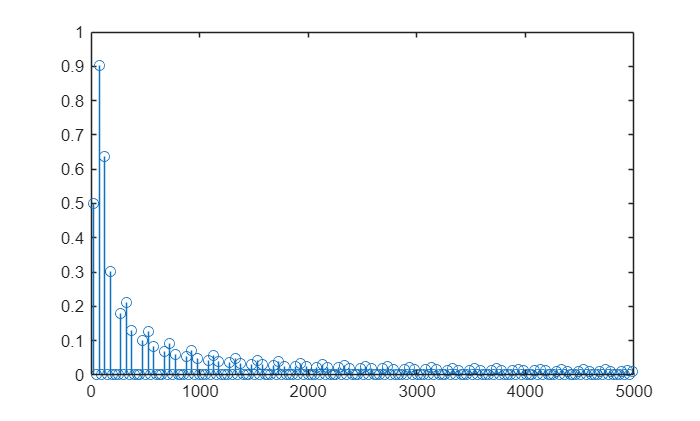

stem(f_axis, X_s), xlim([0 f_s/2]);


% %%%
% s = s.*[cos(2*pi*4000*n_rec)];
% stem(n_rec, s)
% 
% %%%%%%% спектр радиоимпульсов
% FFT_s = fft(s);
% MOD_s = abs(FFT_s);
% X_s = 2/(length(s)/2-1) * MOD_s(1:length(s)/2-1);  % Правильное масштабирование
% X_s(1) = X_s(1)/2;  % DC компонент не удваиваем
% f_axis = (1:(length(s)/2-1)) * (f_s/(length(s)/2-1));
% plot(0:length(s)-1, s)
% stem(f_axis, X_s), xlim([0 f_s/2]);

%%%% создание квадратур от прямоугольного имульса. спеткр их суммы
Q = s.*(-sin(2*pi*500*n_rec/f_s));
I = s.*cos(2*pi*500*n_rec/f_s);
Q_and_I = (I + 1j*Q)

Q_and_I =    1.0000 - 0.0000i   1.0000 - 0.0001i   1.0000 - 0.0001i   1.0000 - 0.0001i   1.0000 - 0.0002i   1.0000 - 0.0002i   1.0000 - 0.0002i   1.0000 - 0.0003i   1.0000 - 0.0003i   1.0000 - 0.0003i   1.0000 - 0.0003i   1.0000 - 0.0004i   1.0000 - 0.0004i   1.0000 - 0.0004i   1.0000 - 0.0005i   1.0000 - 0.0005i   1.0000 - 0.0005i   1.0000 - 0.0006i   1.0000 - 0.0006i   1.0000 - 0.0006i   1.0000 - 0.0007i   1.0000 - 0.0007i   1.0000 - 0.0007i   1.0000 - 0.0008i   1.0000 - 0.0008i   1.0000 - 0.0008i   1.0000 - 0.0008i   1.0000 - 0.0009i   1.0000 - 0.0009i   1.0000 - 0.0009i   1.0000 - 0.0010i   1.0000 - 0.0010i   1.0000 - 0.0010i   1.0000 - 0.0011i   1.0000 - 0.0011i   1.0000 - 0.0011i   1.0000 - 0.0012i   1.0000 - 0.0012i   1.0000 - 0.0012i   1.0000 - 0.0013i   1.0000 - 0.0013i   1.0000 - 0.0013i   1.0000 - 0.0014i   1.0000 - 0.0014i   1.0000 - 0.0014i   1.0000 - 0.0014i   1.0000 - 0.0015i   1.0000 - 0.0015i   1.0000 - 0.0015i   1.0000 - 0.0016i


%plot(0:length(Q_and_I)-1, Q_and_I)
FFT_rec_qa = fft(Q_and_I, N);
MOD_rec_qa = abs(FFT_rec_qa);
X_s = 2/(length(Q_and_I)/2-1) * MOD_rec_qa(1:length(Q_and_I)/2-1);  % Правильное масштабирование
X_s(1) = X_s(1)/2;  % DC компонент не удваиваем
f_axis = (1:(length(Q_and_I)/2-1)) * (f_s/(length(Q_and_I)/2-1));
disp("спектр компексного сигнала")

спектр компексного сигнала


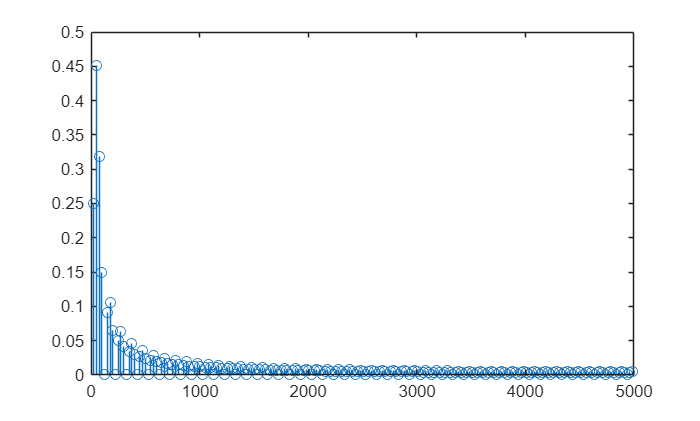

stem(f_axis, X_s), xlim([0 f_s/2]);


% %% спектр домножения Q + I на экспоненту - (cos + sin)
% Q_and_I__sin = Q_and_I.*;
% FFT_Q_and_I__sin = fft(Q_and_I__sin);
% MOD_Q_and_I__sin = abs(FFT_Q_and_I__sin);  % Берем модуль от FFT!
% 
% L = length(Q_and_I__sin);
% X_Q_and_I__sin = 2/L * MOD_Q_and_I__sin(1:L/2+1);  % Правильное масштабирование
% X_Q_and_I__sin(1) = X_Q_and_I__sin(1)/2;  % DC компонент
% 
% f_axis = (0:L/2) * (f_s/L);  % Правильная частотная ось
% 
% disp("спектр X_Q_and_I__sin")
% stem(f_axis, X_Q_and_I__sin);


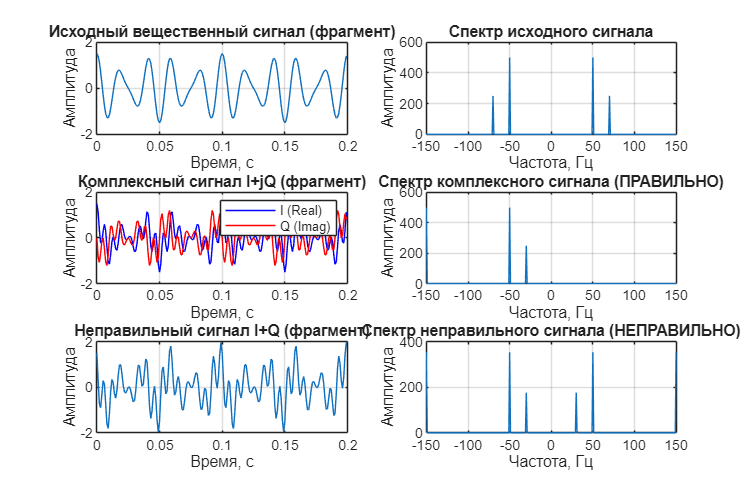

%% Генерация тестового вещественного сигнала
fs = 1000;          % Частота дискретизации, Гц
t = 0:1/fs:1-1/fs;  % Временная шкала (1 секунда)
f_signal = 50;      % Частота полезного сигнала, Гц
f_shift = 100;      % Частота переноса, Гц

% Исходный вещественный сигнал (сумма двух частот)
s = cos(2*pi*f_signal*t) + 0.5*cos(2*pi*(f_signal+20)*t);

%% Квадратурное смешение (получение I и Q компонент)
i_signal = s .* cos(2*pi*f_shift*t);
q_signal = s .* (-sin(2*pi*f_shift*t));

%% ПРАВИЛЬНО: Создание комплексного сигнала
complex_signal = i_signal + 1j * q_signal;

%% НЕПРАВИЛЬНО: Простая сумма без мнимой единицы
wrong_signal = i_signal + q_signal;

%% Анализ спектров
N = length(t);
f = (-N/2:N/2-1) * (fs/N);

% Спектр исходного сигнала
S_original = fftshift(fft(s, N));

% Спектр комплексного сигнала (ПРАВИЛЬНЫЙ)
S_complex = fftshift(fft(complex_signal, N));

% Спектр неправильного сигнала
S_wrong = fftshift(fft(wrong_signal, N));

%% Визуализация результатов
figure('Position', [100, 100, 1200, 800]);

% 1. Исходный сигнал
subplot(3,2,1);
plot(t(1:200), s(1:200));
title('Исходный вещественный сигнал (фрагмент)');
xlabel('Время, с'); ylabel('Амплитуда');
grid on;

subplot(3,2,2);
plot(f, abs(S_original));
title('Спектр исходного сигнала');
xlabel('Частота, Гц'); ylabel('Амплитуда');
xlim([-150, 150]); grid on;

% 2. Комплексный сигнал (правильный)
subplot(3,2,3);
plot(t(1:200), real(complex_signal(1:200)), 'b', 'DisplayName', 'I (Real)');
hold on;
plot(t(1:200), imag(complex_signal(1:200)), 'r', 'DisplayName', 'Q (Imag)');
title('Комплексный сигнал I+jQ (фрагмент)');
xlabel('Время, с'); ylabel('Амплитуда');
legend; grid on;

subplot(3,2,4);
plot(f, abs(S_complex));
title('Спектр комплексного сигнала (ПРАВИЛЬНО)');
xlabel('Частота, Гц'); ylabel('Амплитуда');
xlim([-150, 150]); grid on;

% 3. Неправильный сигнал
subplot(3,2,5);
plot(t(1:200), wrong_signal(1:200));
title('Неправильный сигнал I+Q (фрагмент)');
xlabel('Время, с'); ylabel('Амплитуда');
grid on;

subplot(3,2,6);
plot(f, abs(S_wrong));
title('Спектр неправильного сигнала (НЕПРАВИЛЬНО)');
xlabel('Частота, Гц'); ylabel('Амплитуда');
xlim([-150, 150]); grid on;

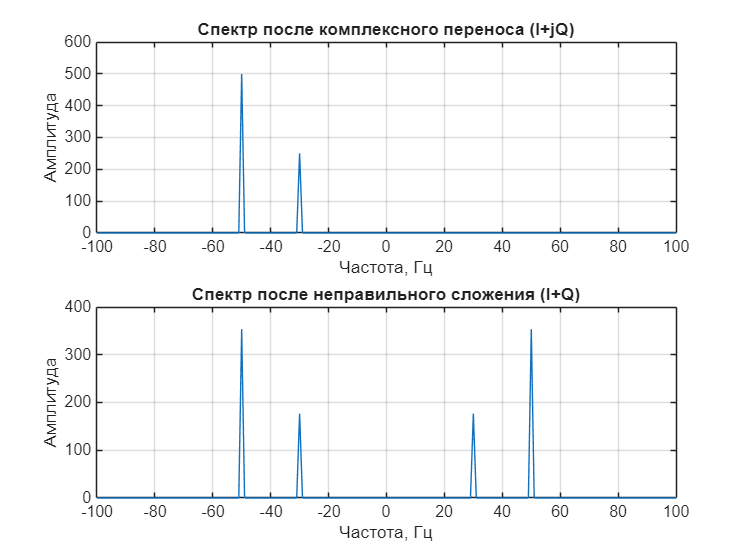


%% Демонстрация переноса спектра
figure('Position', [100, 100, 800, 600]);

% После переноса мы ожидаем сигнал на частоте f_signal - f_shift = -50 Гц
subplot(2,1,1);
plot(f, abs(S_complex));
title('Спектр после комплексного переноса (I+jQ)');
xlabel('Частота, Гц'); ylabel('Амплитуда');
xlim([-100, 100]); grid on;
% Видим один пик на -50 Гц - это и есть наш перенесенный сигнал

subplot(2,1,2);
plot(f, abs(S_wrong));
title('Спектр после неправильного сложения (I+Q)');
xlabel('Частота, Гц'); ylabel('Амплитуда');
xlim([-100, 100]); grid on;

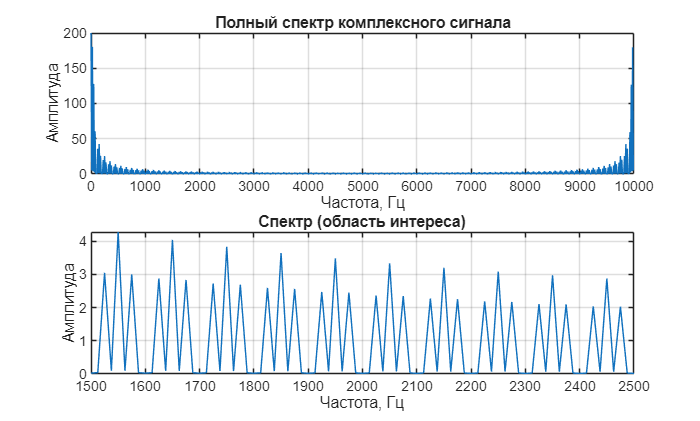

% Видим два симметричных пика - появилось зеркало!